usage: teamwork for week 10

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.5.9

clear all; close all; clc

**1. **条件数**(condition number)是一个矩阵的稳定性或者敏感度的度量，如果一个矩阵的条件数 在1附近，那么它就是良态(well-conditioned)的，如果远大于1，那么它就是 病态(ill-conditioned)的。 矩阵条件数的定义如下：**


$$    $$
    \kappa(A)=\|A\|\|A^{-1}\|
    $$$$


**其中**$$\|A\|$$**是矩阵**$$A$$**的范数。 使用Matlab内置函数`norm`和`inv`求解**希尔伯特矩阵**(Hilbert Matrix)的各类条件数， 并判断其稳定性.**

解：


1-范数下:
1阶希尔伯特矩阵的条件数为1.000000e+00
2阶希尔伯特矩阵的条件数为2.700000e+01
3阶希尔伯特矩阵的条件数为7.480000e+02
4阶希尔伯特矩阵的条件数为2.837500e+04
5阶希尔伯特矩阵的条件数为9.436560e+05
6阶希尔伯特矩阵的条件数为2.907028e+07
7阶希尔伯特矩阵的条件数为9.851949e+08
8阶希尔伯特矩阵的条件数为3.387279e+10
9阶希尔伯特矩阵的条件数为1.099649e+12
10阶希尔伯特矩阵的条件数为3.535233e+13


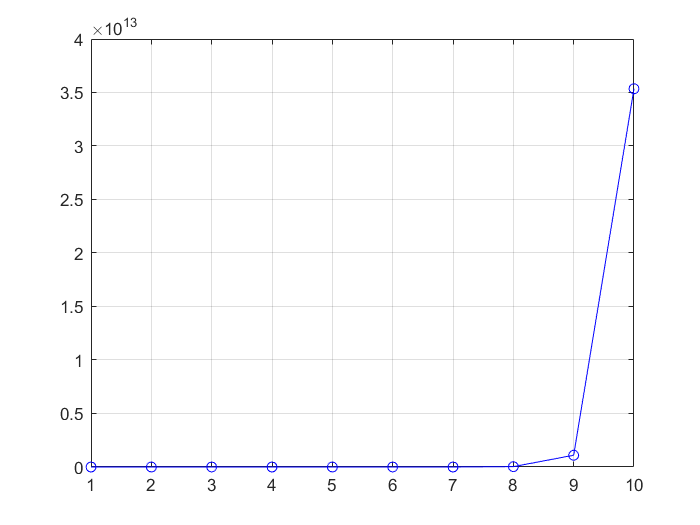

clear all; close all; clc
% 1-范数
Condition_number_of_HM(10, "1")


2-范数下:
1阶希尔伯特矩阵的条件数为1.000000e+00
2阶希尔伯特矩阵的条件数为1.928147e+01
3阶希尔伯特矩阵的条件数为5.240568e+02
4阶希尔伯特矩阵的条件数为1.551374e+04
5阶希尔伯特矩阵的条件数为4.766073e+05
6阶希尔伯特矩阵的条件数为1.495106e+07
7阶希尔伯特矩阵的条件数为4.753674e+08
8阶希尔伯特矩阵的条件数为1.525758e+10
9阶希尔伯特矩阵的条件数为4.931534e+11
10阶希尔伯特矩阵的条件数为1.602503e+13


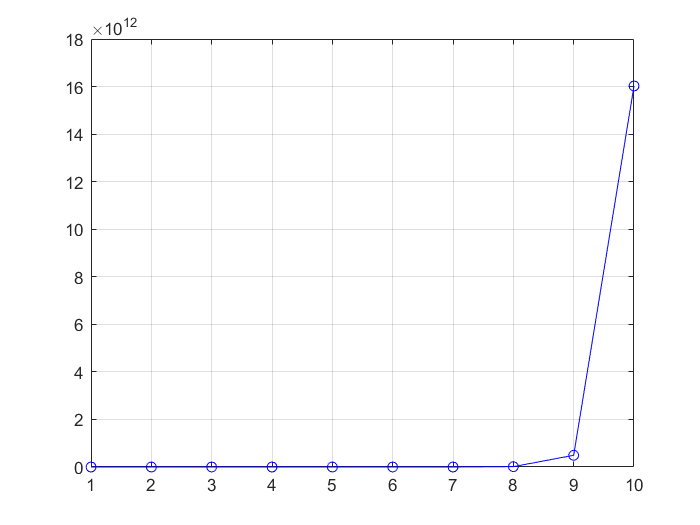

% 2-范数
Condition_number_of_HM(10, "2")


inf-范数下:
1阶希尔伯特矩阵的条件数为1.000000e+00
2阶希尔伯特矩阵的条件数为2.700000e+01
3阶希尔伯特矩阵的条件数为7.480000e+02
4阶希尔伯特矩阵的条件数为2.837500e+04
5阶希尔伯特矩阵的条件数为9.436560e+05
6阶希尔伯特矩阵的条件数为2.907028e+07
7阶希尔伯特矩阵的条件数为9.851949e+08
8阶希尔伯特矩阵的条件数为3.387279e+10
9阶希尔伯特矩阵的条件数为1.099649e+12
10阶希尔伯特矩阵的条件数为3.535233e+13


% inf-范数
Condition_number_of_HM(10, "inf")

从输出结果可以得到，随着希尔伯特矩阵的阶数升高，无论1-范数、2-范数还是无穷范数下的条件数都急剧上升，只有1阶和2阶希尔伯特矩阵的稳定性在三种范数下都相对较低，比较稳定；当阶数大于等于3时，希尔伯特矩阵就是病态的。

Condition_number_of_HM(3, "inf")

**2. 采用牛顿法和高斯消元法求解以下非线性方程组， 并和Matlab内置函数`fsolve`的结果比较：   **


$$   $$
   \begin{array}{ll}
   f_1(x,y) & =y-\frac{1}{2}\left(e^{x/2}+e^{-x/2}\right) & =0\\
   f_2(x,y) & =9x^2+25y^2-225 & =0
   \end{array}
   $$$$


**提示：试探初值可取**$$(2.5, 2.0)$$

解：

首先作图观察

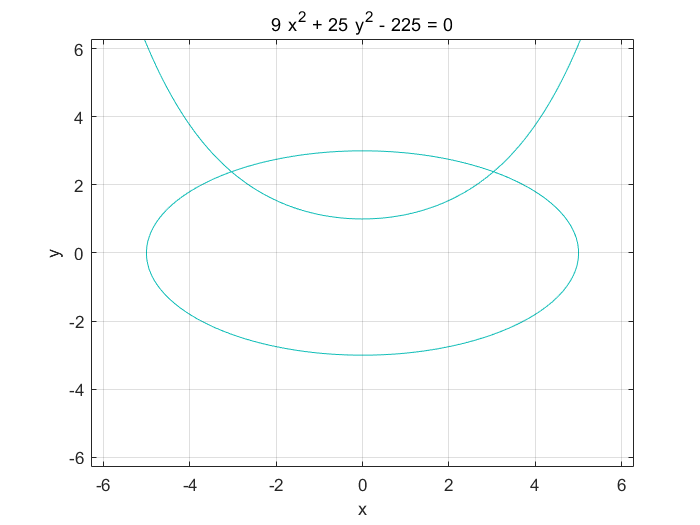

clear all; close all; clc
format long

ezplot('y - 0.5*(exp(x/2)+exp(-x/2))')
hold on
ezplot('9*x^2 + 25*y^2 - 225')
hold off
grid on

通过图像可以发现方程组有两个解

先以（2.5， 2.0）为初始迭代点

牛顿法：

先求解$\frac{\partial f_1}{\partial x},\frac{\partial f_1}{\partial y},\frac{\partial f_2}{\partial x},\frac{\partial f_2}{\partial y},$

syms x y
fun_2_1(x, y) = y - 0.5*(exp(x/2)+exp(-x/2));
fun_2_2(x, y) = 9*x^2 + 25*y^2 - 225;
f_2_1 = matlabFunction(fun_2_1);
f_2_2 = matlabFunction(fun_2_2);
%求解偏导，同时为了矩阵形式规范，求导后结果转变为两个输入参数的函数形式
df_2_1x = matlabFunction(diff(fun_2_1(x, y), x));
df_2_1_x = @(x, y) df_2_1x(x);
df_2_1y = matlabFunction(diff(fun_2_1(x, y), y));
df_2_1_y = @(x, y) df_2_1y();
df_2_2x = matlabFunction(diff(fun_2_2(x, y), x));
df_2_2_x = @(x, y) df_2_2x(x);
df_2_2y = matlabFunction(diff(fun_2_2(x, y), y));
df_2_2_y = @(x, y) df_2_2y(y);

%然后进行迭代
v0_2_1 = [2.5 2]; %  初始迭代点(2.5, 2.0)
tol_2 = 1e-6; %  误差上限
max_n_2 = 100000; %  最多迭代次数
deltav_2 = zeros(size(v0_2_1)); %  为每次迭代的差值分配内存空间
count = 0; %  记录迭代次数
while count < max_n_2
    count = count + 1;
    df_2 = [df_2_1_x(v0_2_1(1), v0_2_1(2)),...
            df_2_1_y(v0_2_1(1), v0_2_1(2));...
            df_2_2_x(v0_2_1(1), v0_2_1(2)),...
            df_2_2_y(v0_2_1(1), v0_2_1(2))];
    f_2 = -1*[f_2_1(v0_2_1(1), v0_2_1(2));...
              f_2_2(v0_2_1(1), v0_2_1(2))];
    deltav_2 = Gauss(df_2,f_2);% 采用高斯消元法求解线性方程组
    if norm(deltav_2) < tol_2
        break
    end
    v0_2_1 = v0_2_1 + deltav_2;
end
fprintf("Newton:\n")

Newton:


if count == max_n_2
    fprintf("it may not converge or the iterations are not enough!\n")
else
    fprintf("方程组的解为x=%f, y=%f", v0_2_1(1), v0_2_1(2))
end

方程组的解为x=3.031155, y=2.385866

再以（-2.5， 2.0）为初始迭代点进行迭代

%进行迭代
v0_2_2 = [-2.5 2]; %  初始迭代点(2.5, 2.0)
tol_2 = 1e-6; %  误差上限
max_n_2 = 100000; %  最多迭代次数
deltav_2 = zeros(size(v0_2_2)); %  为每次迭代的差值分配内存空间
count = 0; %  记录迭代次数
while count < max_n_2
    count = count + 1;
    df_2 = [df_2_1_x(v0_2_2(1), v0_2_2(2)),...
            df_2_1_y(v0_2_2(1), v0_2_2(2));...
            df_2_2_x(v0_2_2(1), v0_2_2(2)),...
            df_2_2_y(v0_2_2(1), v0_2_2(2))];
    f_2 = -1*[f_2_1(v0_2_2(1), v0_2_2(2));...
              f_2_2(v0_2_2(1), v0_2_2(2))];
    deltav_2 = Gauss(df_2,f_2);% 采用高斯消元法求解线性方程组
    if norm(deltav_2) < tol_2
        break
    end
    v0_2_2 = v0_2_2 + deltav_2;
end
fprintf("Newton:\n")

Newton:


if count == max_n_2
    fprintf("it may not converge or the iterations are not enough!\n")
else
    fprintf("方程组的解为x=%f, y=%f", v0_2_2(1), v0_2_2(2))
end

方程组的解为x=-3.031156, y=2.385866

运用高斯消元法求解：

将$f_1(x,y)=0$化为$y=\frac12(e^{x/2}+e^{-x/2})$，将y代入$f_2(x, y)=0$求解出x后，回代到第一个方程中求出y

y_2_fun = @(x) 0.5*(exp(x/2)+exp(-x/2));
fprintf("Gauss:\n")

Gauss:


% 首先以 x=2.5作为初始迭代
x_2_gauss_1 = fzero(@(x) f_2_2(x, y_2_fun(x)), 2.5);
y_2_gauss_1 = y_2_fun(x_2_gauss_1);
fprintf("方程组的解为x=%f, y=%f", x_2_gauss_1, y_2_gauss_1);

方程组的解为x=3.031155, y=2.385866

% 再以 x=-2.5作为初始迭代
x_2_gauss_2 = fzero(@(x) f_2_2(x, y_2_fun(x)), -2.5);
y_2_gauss_2 = y_2_fun(x_2_gauss_1);
fprintf("方程组的解为x=%f, y=%f", x_2_gauss_2, y_2_gauss_2);

方程组的解为x=-3.031155, y=2.385866

运用fsolve进行求解：

fprintf("fsolve:\n")

fsolve:


options = optimoptions('fsolve', 'Display','off');
fun_2 = @root2d_2;
x0_2_1 = [2.5 2];
x_2_check_1 = fsolve(fun_2, x0_2_1, options);
fprintf("方程组的解为x=%f, y=%f", x_2_check_1(1), x_2_check_1(2));

方程组的解为x=3.031155, y=2.385866

x0_2_2 = [-2.5 2];
x_2_check_2 = fsolve(fun_2, x0_2_2, options);
fprintf("方程组的解为x=%f, y=%f", x_2_check_2(1), x_2_check_2(2));

方程组的解为x=-3.031155, y=2.385866

可以看到三种结果得到的解是一样的。

**3. 求解**$$Ax=b$$**, 其中**


$$   $$
   A= \pmatrix {-4 & 1 & &  & & \cr
   1& -4 & 1 & & & \cr
   & 1 & -4 & 1 & & \cr
   & & \ddots & \ddots & \ddots & \cr
   & & & 1 & -4 & 1 \cr
   & & & & 1 & -4},
   b=\pmatrix{
   -27\cr
   -15\cr
   -15\cr
   \vdots\cr
   -15\cr
   -15}
   $$$$


**   使得**$$A$$**为不同维度的稀疏矩阵。 采用托马斯方法(追赶法)求解， 请与Matlab`x=A\b`比较计算结果和计算时间,  评析你的结论。**

**   提示：Matlab内置函数`sparse, spdiags, nnz，spy`产生和观察稀疏矩阵等。**

解：

分别产生$10^k, k=1,2,3\dots7$量级的矩阵，进行分析

clear all; close all; clc
toporder = 6;
time_Thomas = zeros(1, toporder);
time_backslash = zeros(1, toporder);
for k = 1:toporder
    n = 10^k;
    e = ones(n, 1);
    A = spdiags([e -4*e e], -1:1, n, n);
    S = sparse(A);
    whos S
    N = nnz(S);
    fprintf("矩阵中非零元素数为%e", N);
    b = ones(n, 1)*(-15);
    b(1) = -27;
    tic
    x_Thomas = ThomasMethod(S, b)';
    time_Thomas(k) = toc;
    x_backslash = S \ b;
    time_backslash(k) = toc;
    e = norm(x_Thomas - x_backslash);
    fprintf("托马斯方法和backslash的误差为%e", e);
end

  Name       Size            Bytes  Class     Attributes

  S         10x10              536  double    sparse    



矩阵中非零元素数为2.800000e+01

托马斯方法和backslash的误差为1.538370e-15

  Name        Size             Bytes  Class     Attributes

  S         100x100             5576  double    sparse    



矩阵中非零元素数为2.980000e+02

托马斯方法和backslash的误差为4.165926e-15

  Name         Size              Bytes  Class     Attributes

  S         1000x1000            55976  double    sparse    



矩阵中非零元素数为2.998000e+03

托马斯方法和backslash的误差为4.165926e-15

  Name          Size                Bytes  Class     Attributes

  S         10000x10000            559976  double    sparse    



矩阵中非零元素数为2.999800e+04

托马斯方法和backslash的误差为4.165926e-15

  Name           Size                  Bytes  Class     Attributes

  S         100000x100000            5599976  double    sparse    



矩阵中非零元素数为2.999980e+05

托马斯方法和backslash的误差为4.165926e-15

  Name            Size                    Bytes  Class     Attributes

  S         1000000x1000000            55999976  double    sparse    



矩阵中非零元素数为2.999998e+06

托马斯方法和backslash的误差为4.165926e-15

fprintf("\nn x n\t \t\tThomas\t\tbackslash\n")


n x n	 		Thomas		backslash


for k = 1:toporder
    if k < 4
        fprintf("%d x %d \t\t%f秒\t%f秒\n", 10^k, 10^k, time_Thomas(k), time_backslash(k));
    else
        fprintf("%d x %d\t\t%f秒\t%f秒\n", 10^k, 10^k, time_Thomas(k), time_backslash(k));
    end
end

10 x 10 		0.011084秒	0.049051秒
100 x 100 		0.003802秒	0.003842秒
1000 x 1000 		0.030302秒	0.030447秒


10000 x 10000		0.299693秒	0.299925秒
100000 x 100000		4.212702秒	4.214962秒
1000000 x 1000000		272.307966秒	272.340341秒


托马斯方法略微快于backslash，我们推断backslash是对矩阵进行了判断后使用了运算类似于托马斯方法的解法，而托马斯方法直接进行求解，节省了一小部分判断矩阵类型的时间，所以略快于backslash。

**4. 读取某个大小为**$512\times512$**的图像(比如图像为jpg形式，Matlab相关命令：`imread`, `imshow`, `rgb2gray`，`graythresh`, `im2bw`等)， 由此创建你的方矩阵**$$A$$**, 令**$$x$$**的精确解为元素都为1的向量， 由此产生向量**$$b$$**. 使用雅可比迭代法求解线性方程组**$$Ax=b$$**. 你的结果是什么？ 雅可比迭代法收敛吗？ 如果采用Matlab内置的`x=A\b`会有什么结果？**

解：

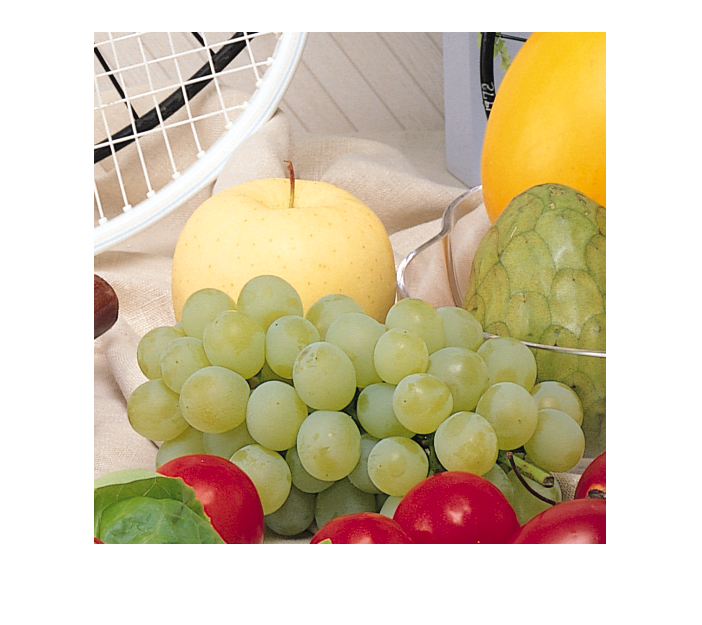

clear all; close all; clc
img = imread("D:\sjtu\2019~2020-2\calculate\第十周作业\fruits.png");
imshow(img)

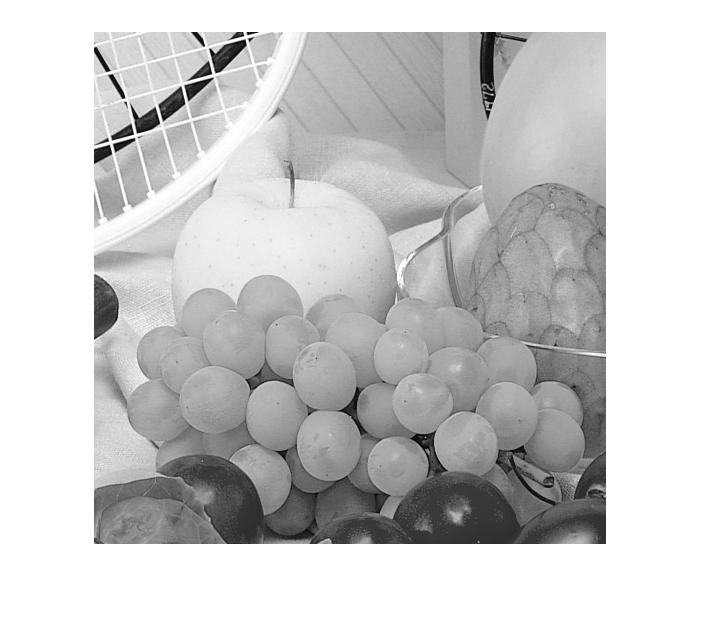

img = rgb2gray(img);
figure
imshow(img)

img = im2double(img);
b_4 = ones(512, 1);
x_4_backslash = img \ b_4

x_4_backslash =    3.131084642595686
  -3.357085278113870
   0.316523627825467
   1.951339471559538
  -1.776447199040814
   2.150779825090612
  -1.281686739040365
   0.039690308452845
  -1.602925554333125
   0.087299548857198


[x_4_Jacobi, k_4_Jacobi, ~] = Jacobi(img, b_4, ones(512, 1), 1e-5, 100000)

x_4_Jacobi =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


k_4_Jacobi =       100000


**5. PageRank算法**

**   我们可以从某个根网页出发通过一系列超链接到达其他的网页。 假设这些所有网页的集合为**$$W$$**,  **$$n$$**是**$$W$$**集合中网页总数。 **

**   现在建立部分互联网的**$$n\times n$$**的**关联矩阵****$$G$$**（connectivity matrix）. 若从网页**$$j$$**到网页**$$i$**存在一个链接， 则**$$g_{ij}=1$$**;  否则**$$g_{ij}=0$$**. **$ $G$$**矩阵第**$$j$$**列就显示了网页**$$j$$**的所有外向链接， 其所有非零元素的数目就是**$$W$$**集合中存在的超链接总数。**

**(1) 以下图为例， 考虑互联网四结点子集图， 问网页关联矩阵**$$G$$**是什么？**

解：关联矩阵中，所有为1的元素表示外向链接，故当$g_{ii}=0$即网页自身到自身不算外向链接。


$$G=\pmatrix{0 & 0 & 0 & 0 \cr
1 & 0 & 1 & 0 \cr
1 & 0 & 0 & 1\cr
0 & 0 & 1 & 0}$$


clear all; close all; clc
G_5 = [0,0,0,0;...
       1,0,1,0;...
       1,0,0,1;...
       0,0,1,0]

G_5 =      0     0     0     0
     1     0     1     0
     1     0     0     1
     0     0     1     0


**   (2) 用向量**$$c$$**表示网页的**出度**， 即**$$c_j$$**表示从网页**$$j$$**出发的超链接的数量，**


$$   $$
   c_j=\sum_{i=1}^{n}G_{ij}
   $$$$


**   求出上图实例中的**$$c$$**.**

解：将出度表示为行向量

c_5 = sum(G_5, 1)

c_5 =      2     0     2     1



$$c=\pmatrix{2 & 0 & 2 & 1}$$


** (3) PageRank算法： 假设每次仅以很小的可能，从互联网里选中某个随机网， 这种随机行走称为马尔科夫链, 或称马尔科夫过程(Markov chain/process)； 也就是从任意的一个试探状态起， 我们用一个**$$n$$**行的列向量**$$x^{(1)}$$**来表示这样的状态， 其中第**$$j$$**行元素**$$x^{(1)}_j$$**表示网页**$$j$$**被点击的概率， 那么在一次随机行走后， 向量**$$x^{(1)}$$**将被更新一次:**


$$   $$
   x^{(2)}=Ax^{(1)}
   $$$$


**   其中**$$A$$**称为马尔科夫链的**转移概率矩阵**(transition probability matrix),  它的元素都严格地在0-1之间， 第**$$j$$**列表示从网页**$$j$**跳到其他网页的概率， 其列元素之和等于1。 我们假定**$$p$$**为超链接随机行走的概率， **$$p=0.85$$**是其典型取值， 那么， **$$1-p$$**就是选定任意网页而不再继续外链的概率， **$$\delta=(1-p)/n$$**是选定了某一具体网页。 这样， **$$A$$**元素的取值如下**


$$$$A_{ij}=
\begin{cases}
p\frac{G_{ij}}{c_j}+\delta, &  c_j\neq 0\\
 \frac{1}{n},  & c_{j}=0
\end{cases}$$
\end{CJK*}
\end{document}
$$


**   请根据上述说明计算(1)实例中的转移概率矩阵**$$A$$**.**

解：

p_5 = 0.85;
A_5 = Transition_probability_matrix(G_5, c_5, p_5)

A_5 =    0.037500000000000   0.250000000000000   0.037500000000000   0.037500000000000
   0.462500000000000   0.250000000000000   0.462500000000000   0.037500000000000
   0.462500000000000   0.250000000000000   0.037500000000000   0.887500000000000
   0.037500000000000   0.250000000000000   0.462500000000000   0.037500000000000


**(4) 经过多次随机行走后，**$ $x^{(k)}$$**将收敛到一个某个值，这就是网页的PageRank值， 即**


$$   $$
   x=Ax
   $$$$


   $$x$$**的元素全为正数且小于1， 并且**


$$   $$
   \sum_{j=1}^nx_j=1
   $$$$


**   求解**$$x=Ax$$**的一个算法是： 首先求解**


$$   $$
   (I-pGD)x= \delta e
   $$$$


**   其中**$$I$$**是单位矩阵，**$$D$$**是出度倒数形成的对角矩阵**


$$$$d_{jj}=
\begin{cases}
\frac{1}{c_j},& c_j\neq 0\\
 0, & c_j=0
\end{cases}$$
\end{CJK*}
\end{document}$$


   $$I$$**, **$$G$$**, **$$D$$**都作为稀疏矩阵处理。**$ $e$$**是与**$$x$$**一样维度的向量， 其元素均为1.  然后再对所得的**$$x$$**采用比例因子进行定标处理， 使其满足等式**$$\sum_{j=1}^nx_j=1$$**。 **

**   请利用(1)给出的实例， 参考样本程序， 使用**LU分解法**求解**$$x$$**,  从而得到网站点击率的排名。**

n_5 = length(c_5);
D_5 = spdiags(1./c_5', 0, n_5, n_5);
D_5(2, 2) = 0;
I_5 = speye(n_5, n_5);
e_5 = ones(n_5, 1);
% 先用backslash进行求解
x_5_backslash = (I_5 - p_5*G_5*D_5) \ (1-p_5/n_5*e_5);
x_5_backslash = x_5_backslash / sum(x_5_backslash)

x_5_backslash =    0.099859785917034
   0.293457816080161
   0.355664990937382
   0.251017407065422


x_5_Doolittle = DoolittleMethod((I_5 - p_5*G_5*D_5), ((1-p_5)/n_5*e_5));
x_5_Doolittle = x_5_Doolittle / sum(x_5_Doolittle)

x_5_Doolittle =    0.099859785917034
   0.293457816080161
   0.355664990937382
   0.251017407065422


使用backslash和Doolittle得到的x基本相等

rank_5 = ones(n_5, 1); % 为排名向量分配内存空间
fprintf("节点\t排名")

节点	排名

for k = 1:n_5
    for i = 1:n_5
        if x_5_Doolittle(k) < x_5_Doolittle(i)
            rank_5(k) = rank_5(k) + 1;
        end
    end
    fprintf("%d\t%d\n", k, rank_5(k))
end

1	4
2	2
3	1
4	3


****************************************************functions**************************************************

Condition_number_of_HM：根据输入的变量n，即矩阵的阶数，以及给定三种条件数的1-范数或2-范数，或无穷范数下，求出1~n阶希尔伯特矩阵的条件数，并作图表示

args：

    n：希尔伯特矩阵的阶数

    m："1"表示1-范数对应cond(A,1) 、

           "2"表示2-范数对应cond(A,2)、

           "inf"表示无穷范数对应cond(A,"inf")

function Condition_number_of_HM(n, m)
    switch m
        case "1"
            fprintf("\n1-范数下:\n")
        case "2"
            fprintf("\n2-范数下:\n")
        otherwise
            fprintf("\ninf-范数下:\n")
    end
    K = zeros(1,n);
    for k = 1:n
        HM = ones(k, k);
        for i = 1:k
            HM(i, :) = HM(i, :) ./ (i:(i+k-1));
        end
        %K(k) = norm(HM)*norm(inv(HM));
        switch m
            case "1"
                K(k) = cond(HM, 1);
            case "2"
                K(k) = cond(HM, 2);
            otherwise
                K(k) = cond(HM, "inf");
        end
        fprintf("%d阶希尔伯特矩阵的条件数为%e\n", k, K(k));
    end
    plot(1:n,K,'b-o')
    grid on
end

root2d_2：第2题用于fsolve求解

function F = root2d_2(x)
    F(1) = x(2) - 0.5.*(exp(x(1)./2)+exp(-x(1)./2));
    F(2) = 9.*x(1).^2 + 25.*x(2).^2 - 225;
end

ThomasMethod：用托马斯方法求解三对角（带状）矩阵的线性方程组

function x = ThomasMethod(A,b)
%
% ThomasMethod uses Thomas method to find the solution
% vector x of a tridiagonal system Ax = b.
%
% x = ThomasMethod(A,b) where
%
% A is a tridiagonal n-by-n coefficient matrix,
% b is the n-by-1 vector of the right-hand sides,
%
% x is the n-by-1 solution vector.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 4.3.4, p.111

n = size(A,1);
d = diag(A); % Vector of diagonal entries of A
l = [0;diag(A, -1)]; % Vector of lower diagonal elements
u = [diag(A,1);0]; % Vector of upper diagonal elements

u(1) = u(1)/d(1); b(1) = b(1)/d(1); % First equation

for k = 2:n-1 % The next n-2 equations
    den = d(k) - u(k-1)*l(k);
    if den == 0
        x = 'failure, division by zero';
        return
    end
    u(k) = u(k)/den; 
    b(k) = (b(k)-b(k-1)*l(k))/den;
end
b(n) = (b(n)-b(n-1)*l(n))/(d(n)-u(n-1)*l(n));
% Last equation
x(n) = b(n);
for k = n-1:-1:1
    x(k) = b(k) - u(k)*x(k+1);
end
end

Jacobi：用雅可比方法求解线性方程组$Ax=b$

从A中得到矩阵$D=\pmatrix{a_{11} & 0 & \dots &0   \cr 0 & a_{22} & \dots & 0 \cr \vdots & \vdots & \ddots & \vdots \cr 0 & 0 & &a_{nn}}$，由迭代关系$x^{(k+1)}=D^{-1}b-D^{-1}(A-D)x^{(k)}$，当达到终止条件$|x^{(k+1)}-x^{(k)}| \le \epsilon$或达到最大迭代次数时，终止迭代。

args：

    A：系数矩阵

    b

    x0：初始估计值

    epsilon：误差上限

    max_n：最多迭代次数

function [x, k, Jnorm] = Jacobi(A, b, x0, tol, kmax)
%
% Jacobi uses the Jacobi iteration method to approximate
% the solution of Ax = b.
%
% [x, k, MJnorm] = Jacobi(A, b, x0, tol, kmax) where
%
% A is the n-by-n coefficient matrix,
% b is the n-by-1 right-hand side vector,
% x0 is the n-by-1 initial vector (default zeros),
% tol is the scalar tolerance for convergence (default 1e-4),
% kmax is the maximum number of iterations (default 100),
%
% x is the n-by-1 solution vector,
% k is the number of iterations required for convergence,
% MJnorm is the infinite norm of the Jacobi iteration
% matrix.
% Esfandiari Ramin, Numerical Methods for Engineers and Scientists using
% Matlab
% Section 4.5, p.130

if nargin < 3 || isempty(x0)
    x0 = zeros(size(b));
end
if nargin < 4 || isempty(tol)
    tol = 1e-4;
end
if nargin < 5 || isempty(kmax)
    kmax = 100;
end

x(:, 1) = x0;
D = diag(diag(A)); At = A - D;
L = tril(At);
U = triu(At);

% Norm of Jacobi iteration matrix
P = D\b;
Q = -D\(L + U); Jnorm = norm(Q, inf);


% Perform iterations up to kmax
for k = 1:kmax
    x(:, k+1) = P + Q*x(:, k) ; % Compute next approximation
    if norm(x(:, k+1) - x(:, k)) < tol, break; end    % Check convergence
end

x = x(:, end);
end

Transition_probability_matrix：求转移概率矩阵$$$A_{ij}=
\begin{cases}
p\frac{G_{ij}}{c_j}+\delta, &  c_j\neq 0\\
 \frac{1}{n},  & c_{j}=0
\end{cases}$$
\end{CJK*}
\end{document}
$

args：

    G：关联矩阵

    c：网页出度

    p：超链接随机行走的概率

function A = Transition_probability_matrix(G, c, p)
    A = zeros(size(G));
    n = length(c);
    for j = 1:n
        if c(j) == 0
            A(:, j) = ones(n, 1) ./ n;
        else
            for i = 1:n
                A(i, j) = p*G(i, j)/c(j) + (1-p)/n;
            end
        end
    end
end

DoolittleFactor：用Doolittle算法求解A的L和U矩阵

function [L, U] = DoolittleFactor(A)
% Esfandiari,Ramin S, Numerical Methods for Engineers and Scientists 
% Section 4.4, p.115
%
% DoolittleFactor returns the Doolittle factorization of
% matrix A.
%
% [L U] = DoolittleFactor(A) where
%
% A is an n-by-n matrix,
%
% L is the lower triangular matrix with 1’s along the
% diagonal,
% U is an upper triangular matrix.
%
n = size(A,1);
L = eye(n); U = zeros(n,n); % Initialize
for i = 1:n
    U(i,i) = A(i,i)-L(i,1:i-1)*U(1:i-1,i);
    for j = i+1:n
        U(i,j) = A(i,j)-L(i,1:i-1)*U(1:i-1,j);
        L(j,i) = (A(j,i)-L(j,1:i-1)*U(1:i-1,i))/U(i,i);
    end
end
end

DoolittleMethod(A,b)：用Doolittle算法求解$Ax=b$

function x = DoolittleMethod(A,b)
% Esfandiari,Ramin S, Numerical Methods for Engineers and Scientists 
% Section 4.4, p.116
%
% DoolittleMethod uses the Doolittle factorization of
% matrix A and solves the ensuing triangular systems to
% find the solution vector x.
%
% x = DoolittleMethod(A,b) where
%
% A is the n-by-n coefficient matrix,
% b is the n-by-1 vector of the right-hand sides,
%
% x is the n-by-1 solution vector.
%
[L, U] = DoolittleFactor(A);
% Find Doolittle factorization of A
n = size(A,1);
% Solve the lower triangular system Ly = b (forward
% substitution)
y = zeros(n,1);
y(1) = b(1);
for i = 2:n
    y(i) = b(i)-L(i,1:i-1)*y(1:i-1);
end
% Solve the upper triangular system Ux = y (back
% substitution)
x = zeros(n,1);
x(n) = y(n)/U(n,n);
for i = n-1: -1:1
    x(i) = (y(i)-U(i,i+1:n)*x(i+1:n))/U(i,i);
end
end

Gauss：高斯消元法求解线性方程组

function x = Gauss(a,b)
% The function solves a system of linear equations [a] [x] = [b] using the Gauss
% elimination method.
% Input variables:
% a The matrix of coefficients.
% b Right-hand-side column vector of constants.
% Output variable:
% x A column vector with the solution.
% Amos Gilat, Numerical Methods for Engineers and Scientists 
% Section 4.2, p.108-109

ab = [a,b]; % Append the column vector [ b] to the matrix [a]
[R, C] = size(ab);
for j = 1:R - 1
    for k = j + 1:R     
        ab(k,j:C) = ab(k,j:C)- ab(k,j)/ab(j ,j)*ab(j,j:C);
    end
end
x = zeros(R,1);
x(R) = ab(R,C)/ab(R,R);
for k = R - 1:-1:1
    x(k) = (ab(k,C) - ab(k,k + 1:R)*x(k + 1:R))/ab(k,k);
end
end